# Lithium Harvesting

Harvesting lithium sustainably is important for increasing available battery storage, a key step for increasing global reliance on time variable renewable energy sources. One technique for harvesting lithium is the use of a Lithium-Ion Sieve (LIS) with brine from a desalination processes. LIS leverages an ion exchange process, which operates in 4 stages.

- Service - this is where water containing Li+ ions is passed through the LIS. Li+ ions replace H+ ions held in the sieve.

- Backwashing -  flow is reversed and clean water is passed through to ensure any "gunk" is cleaned out

- Regeneration - an acid solution, often HCl is passed through the membrane. The heavy concentration of H+ ions are used to reverse the initial service step.

- Rinsing - the membrane is cleaned again flushing out the acid for next service stage.

The ion-exchange equations block models these dynamics using a Langmuir adsorption model which depends on three parameters, a "size" parameter (how many ions can the sieve hold), a "selectivity" parameter (if you had the same amount of ion x and ion y in the solution, what would the equilibrium ratio be for adsorbed x/adsorbed y), and a "speed" parameter (users provide for one of x or y adsorption, ideally fitted to experimental data). The LithiumIonSieve.slx model demonstrates this functionality.

open_system('LithiumIonSieve.slx')

we can set run times for the different stages and run to see these stages working

t_service = 3600*8;     % [s] Service time
t_regen = 3600*2;       % [s] Regeneration time
t_clean = 3600*1;       % [s] Backwashing and rinsing time
set_param('LithiumIonSieve/In Flow Control','gain','1')  % L/min
out = sim('LithiumIonSieve.slx');
t_hr = plot_li_harvested(out.simlog);
add_cycle_shading(t_hr, t_service, t_regen, t_clean);

The faint shading in the above plot represents the different stages.

## Increasing Lithium Harvesting Efficiency

We can notice in the plot that we are losing ~1/6 of the total lithium mass entering the system. Maybe we have a limited amount of brine resource and would like to recover more of the lithium. We can do this effectively by reducing our flow rate through the system, however, this will decrease the total lithium we can harvest in the 48 hour simulation period.

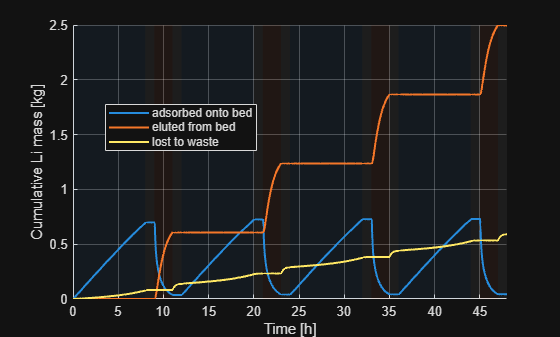

set_param('LithiumIonSieve/In Flow Control','gain','0.2')  % L/min
t_service = 3600*20;     % [s] Service time
out = sim('LithiumIonSieve.slx');
t_hr = plot_li_harvested(out.simlog);
add_cycle_shading(t_hr, t_service, t_regen, t_clean);

We can see that although we increased the efficiency slightly, we also experienced a massive drop in the amount of lithium extracted.

## Increasing Lithium Harvesting Rate

In another hypothetical, maybe we have a situation where brine is plentiful and our goal is just to extract as much lithium as quickly as possible. In this situation, we'd want to increase our flow rates.

set_param('LithiumIonSieve/In Flow Control','gain','2')  % L/min
t_service = 3600*4;     % [s] Service time
out = sim('LithiumIonSieve.slx');
t_hr = plot_li_harvested(out.simlog);
add_cycle_shading(t_hr, t_service, t_regen, t_clean);

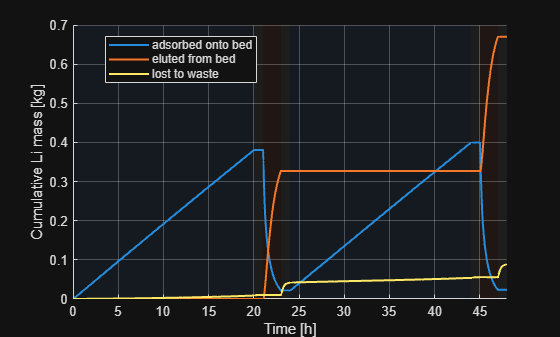

function t_hr = plot_li_harvested(simlog)
    x_window = [0 48];
    ie     = simlog.Ion_Exchange_EQs_SS;
    t       = ie.theta_x.series.time;

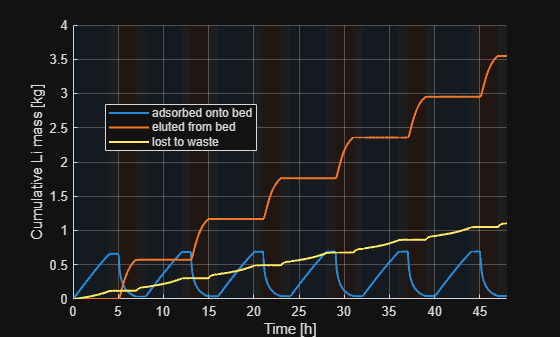

    t_hr    = t/3600;
    mdot_x  = ie.mdot_x.series.values;    % Li mass flow into bed [kg/s]
    waste   = simlog.Waste;
    li_lost = waste.mdot_A_x.series.values; % Li mass lost through waste stream [kg/s]
    li_conc = simlog.Li_Concentrate;
    li_out  = li_conc.mdot_A_x.series.values; % Li mass flow harvested [kg/s]
    mLi_in  = cumtrapz(t, -mdot_x);
    mLi_out = cumtrapz(t, li_out);
    mLi_lost= cumtrapz(t, li_lost);

    figure('Name','Cumulative Li in/out');
    line(t_hr, mLi_in,  'LineWidth', 1.5);
    line(t_hr, mLi_out, 'LineWidth', 1.5);
    line(t_hr, mLi_lost,'LineWidth', 1.5);
    grid on;
    xlabel('Time [h]');
    ylabel('Cumulative Li mass [kg]');
    legend({'adsorbed onto bed','eluted from bed','lost to waste'}, 'Location','best');
    xlim(x_window);
end

function add_cycle_shading(t_hr, t_service, t_regen, t_clean)
% Shade service / regen / clean phases along the current x-axis window.
xl = xlim;
t_end_hr = min(t_hr(end), xl(2));
cycle    = (t_service + t_regen + 2*t_clean) / 3600;
if cycle <= 0, return; end
yl = ylim; ax = gca; hold(ax, 'on');
t0 = 0;
colors = struct( ...
    'service',[0.2 0.6 1.0], ...
    'regen',  [1.0 0.4 0.2], ...
    'clean',  [0.8 0.8 0.8]);

FaceAlpha = 0.06;
while t0 < t_end_hr
    segs = { 'service', t_service/3600; ...
             'clean',   t_clean/3600;   ...
             'regen',   t_regen/3600;   ...
             'clean',   t_clean/3600 };
    for k = 1:size(segs,1)
        w = segs{k,2};
        if w <= 0, continue; end
        x1 = t0; x2 = min(t0 + w, t_end_hr);
        patch([x1 x2 x2 x1], [yl(1) yl(1) yl(2) yl(2)], ...
              colors.(segs{k,1}), 'EdgeColor','none', ...
              'FaceAlpha',FaceAlpha, 'HandleVisibility','off');
        t0 = x2;
        if t0 >= t_end_hr, break; end
    end
end
% keep data on top of shading
chH = get(ax, 'Children');
isPatch = arrayfun(@(h) isa(h,'matlab.graphics.primitive.Patch'), chH);
set(ax, 'Children', [chH(~isPatch); chH(isPatch)]);
ylim(yl);
end